# Strange behaviors in simple circuits

7 Feb 24 B. Rasnow

Exploring Johnson noise with a Raspberry pi Pico I came across some strange behavior in this circuit: 

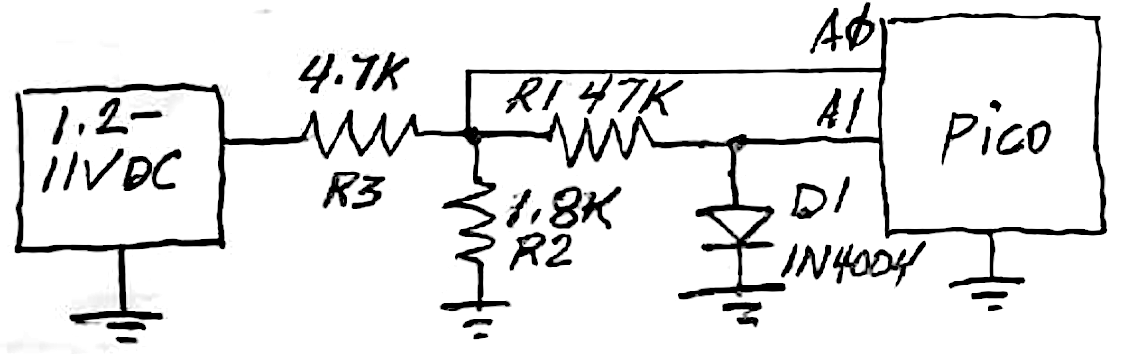

    Figure 1. Schematic

R2 (=2k||20k) and R3 make a stiff voltage divider reducing the <11.2V LM317 DC voltage to < 11.2V*1.8/(1.8+4.7) = 3.1V, safe for the Pico to measure on input A0. A1 measures the voltage across silicon rectifier diode D1, R1 limiting the diode's current. The Pico measured 1000 samples on each input at a rate of 40985 samples/second/channel, while the power supply voltage was slowly adjusted manually with its potentiometer. Data was recorded in the following loop:

The first line triggers Pico to acquire 1000x2 data points in `dat.data`, the next line saves the mean and standard deviations (rms noise), and the 3rd line prints a status indicator after a 200msec pause. Superimposing 3 trials produced the following results: 

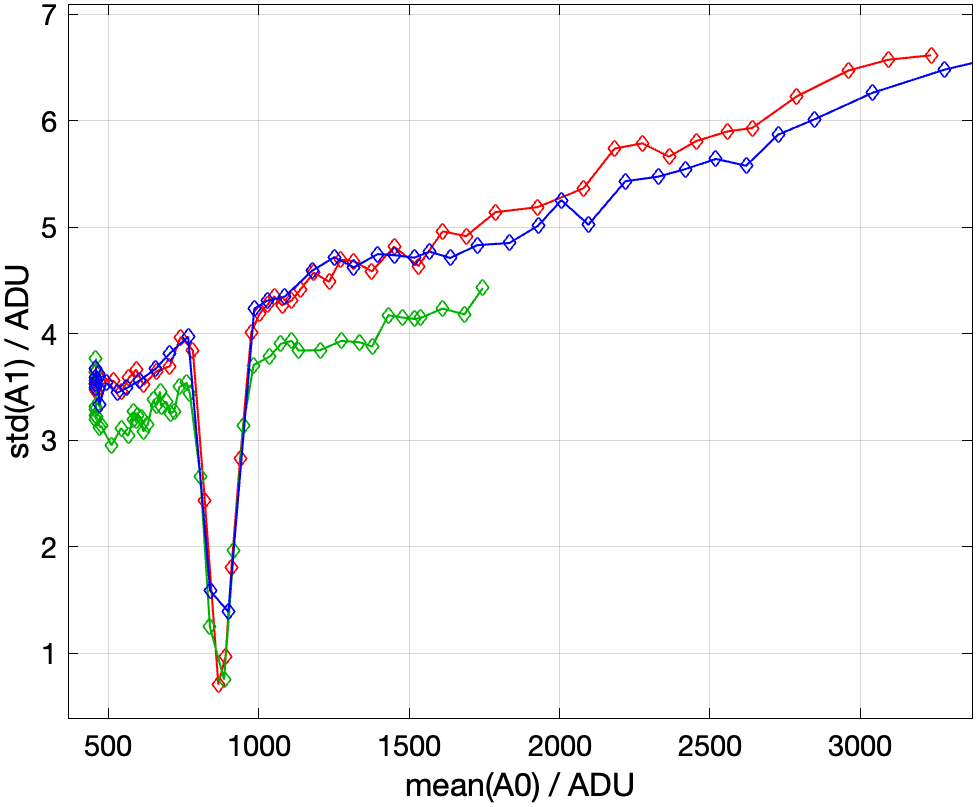

        Figure 2. Noise across the diode dips on 3 trials.

The dip in the noise of the diode is highly repeatable, occuring at a voltage ~ 

866 * 3.3 / 2^12

ans = 0.6977

just where the diode turns on. So why would a diode's noise drop by a factor ~3 and then pop up again?? What solid state physics might be behind this -- what theory explains this?

Before diving into theory, let's look closer at the actual data. Here's a typical trace of the raw data below and at the dip: 

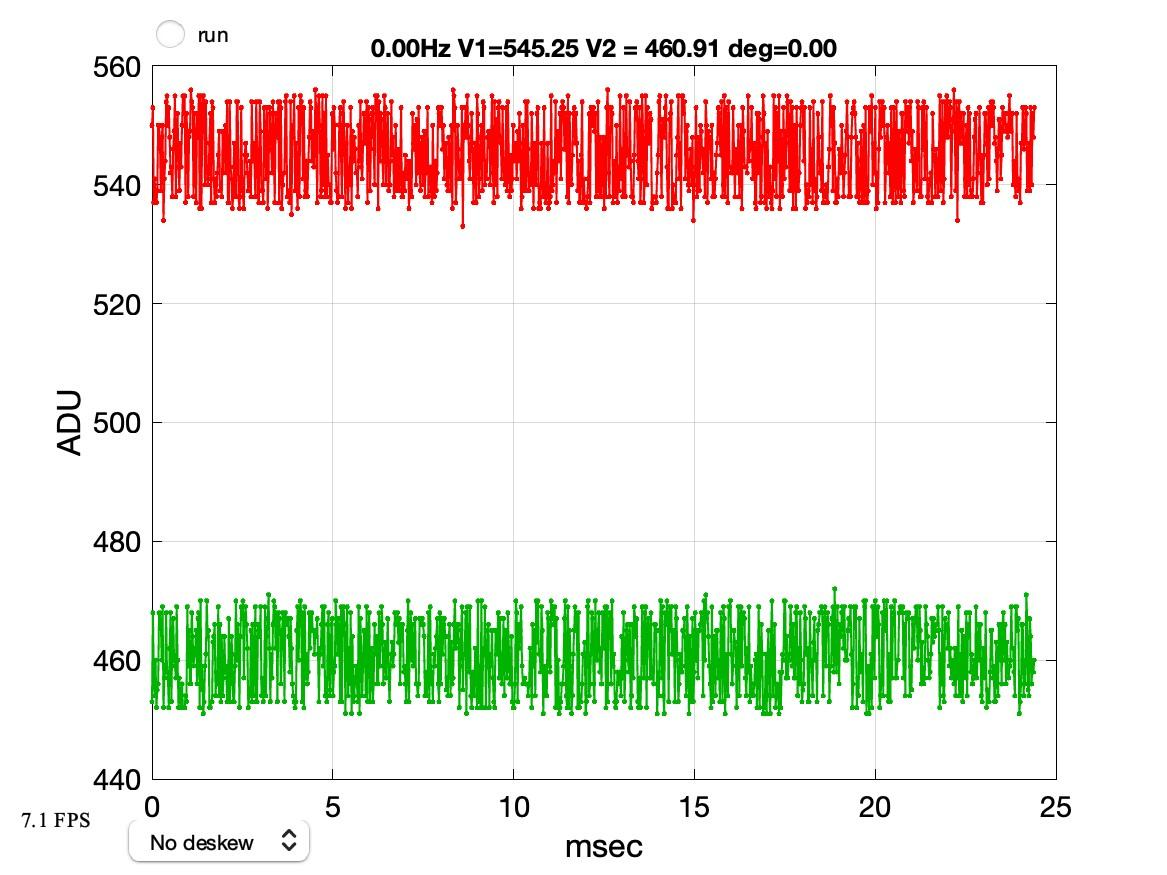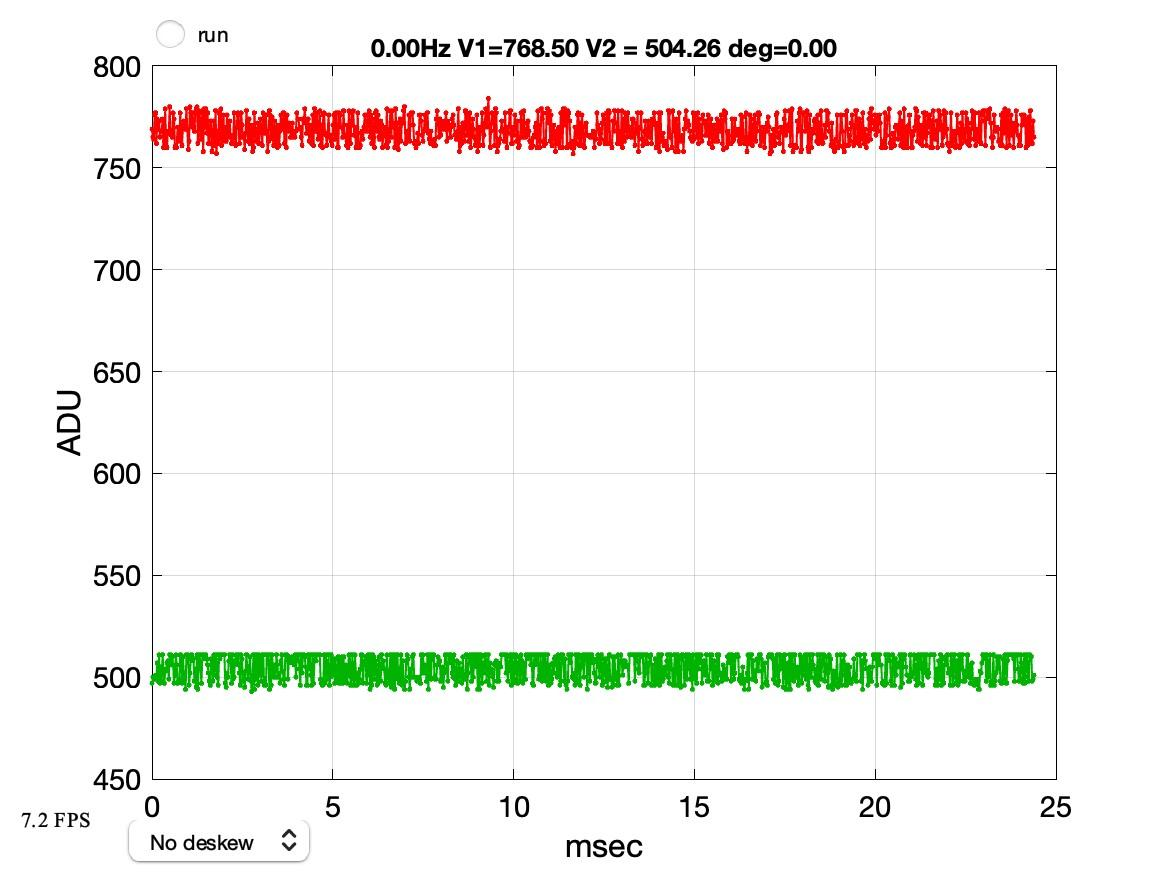

        Figure 3. A. V1 = 545ADU ~ .44V, noise on both channels are comparable. B. V1 = 768ADU ~ 0.62V, the diode is at 504ADU ~ .41V.

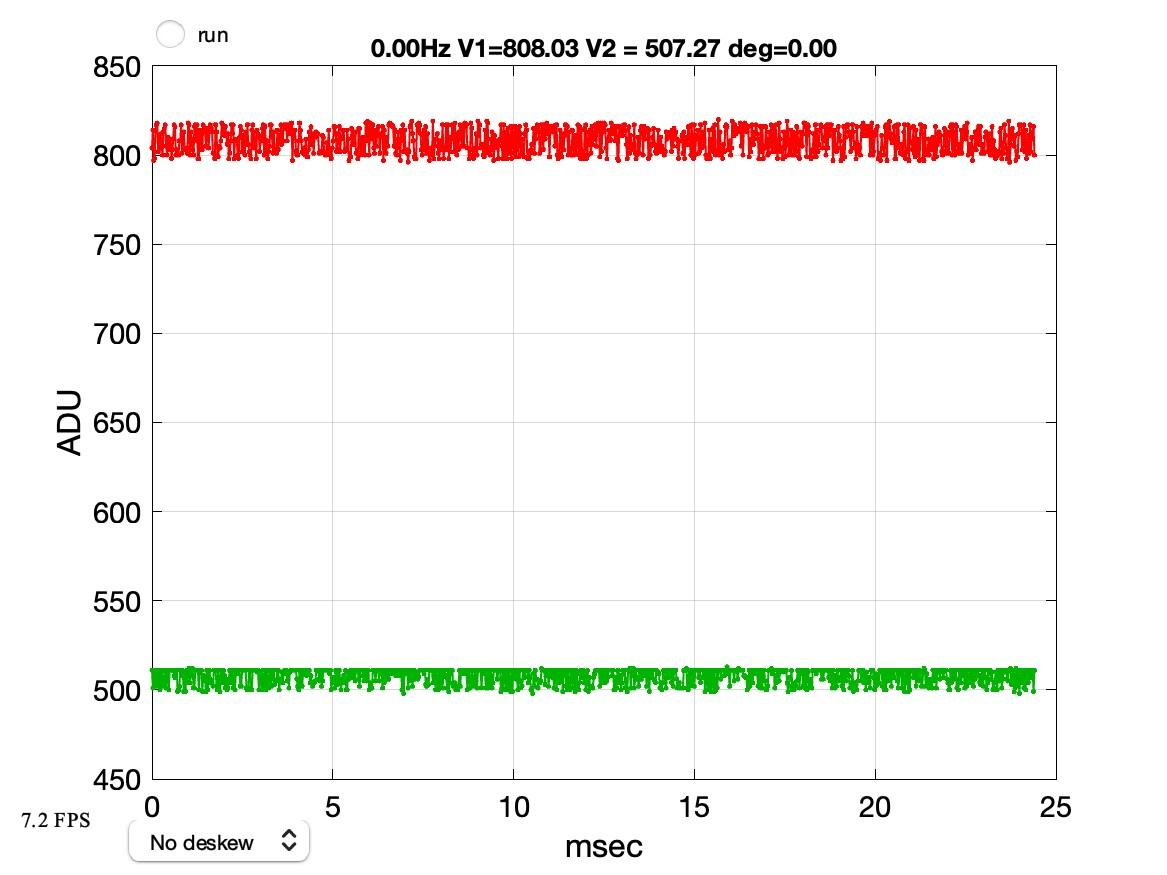 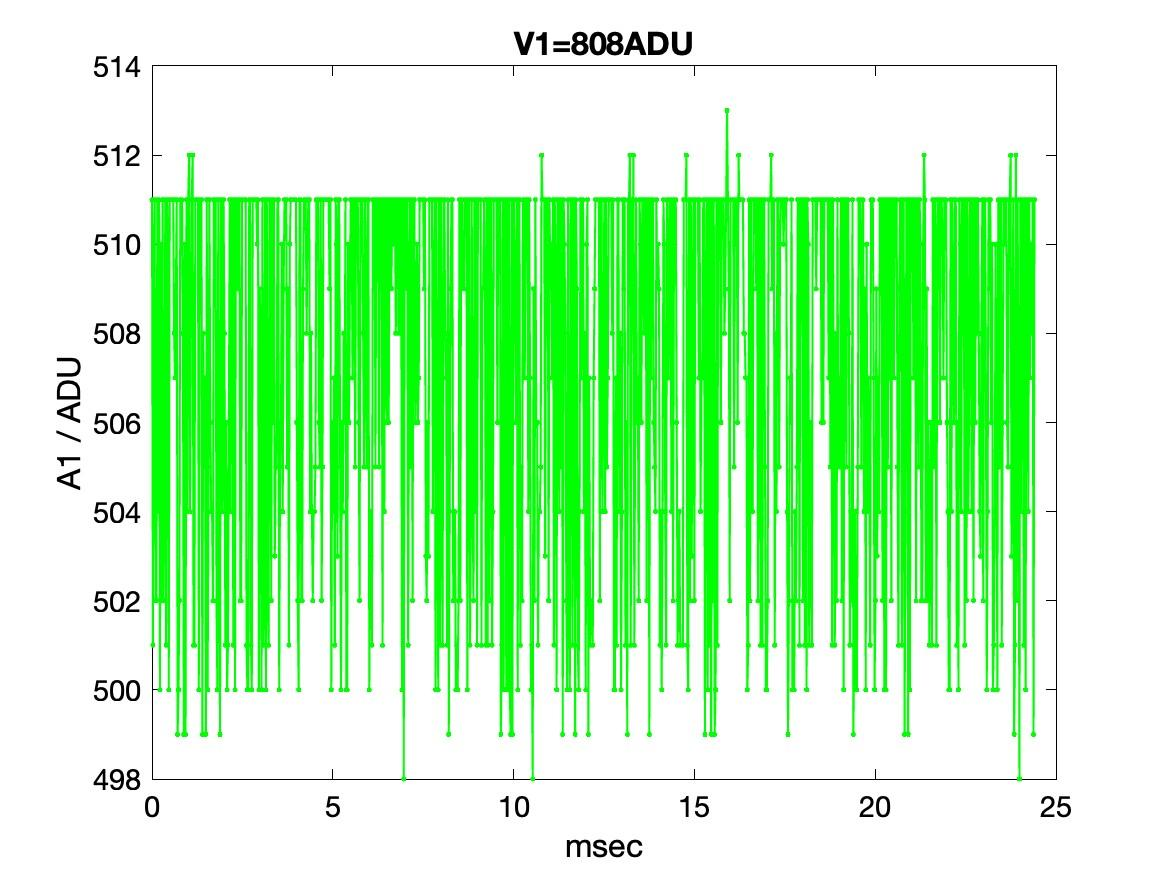     

    Figure 4. V1 = 808ADU, the decrease in diode noise is apparent -- but just on the *upper* side, as evident by zooming in (right).

### Conclusion

This isn't magical solid state physics in the diode, but diabolical ADC behavior in the Raspberry pi Pico. This Pico appears to have a reluctance to cross the 511ADU threshold. A better way to demonstrate this is with a slow triangle wave -- one of the reasons triangle waves are common on function generators. A plateau at an ADC level would show up as a "differential nonlinearity" ([https://en.wikipedia.org/wiki/Differential_nonlinearity](https://en.wikipedia.org/wiki/Differential_nonlinearity)). Our function generator's triangle wave has a DC offset that just so happens to be right around 511ADU so here's a zoomed in bottom of the triangle.

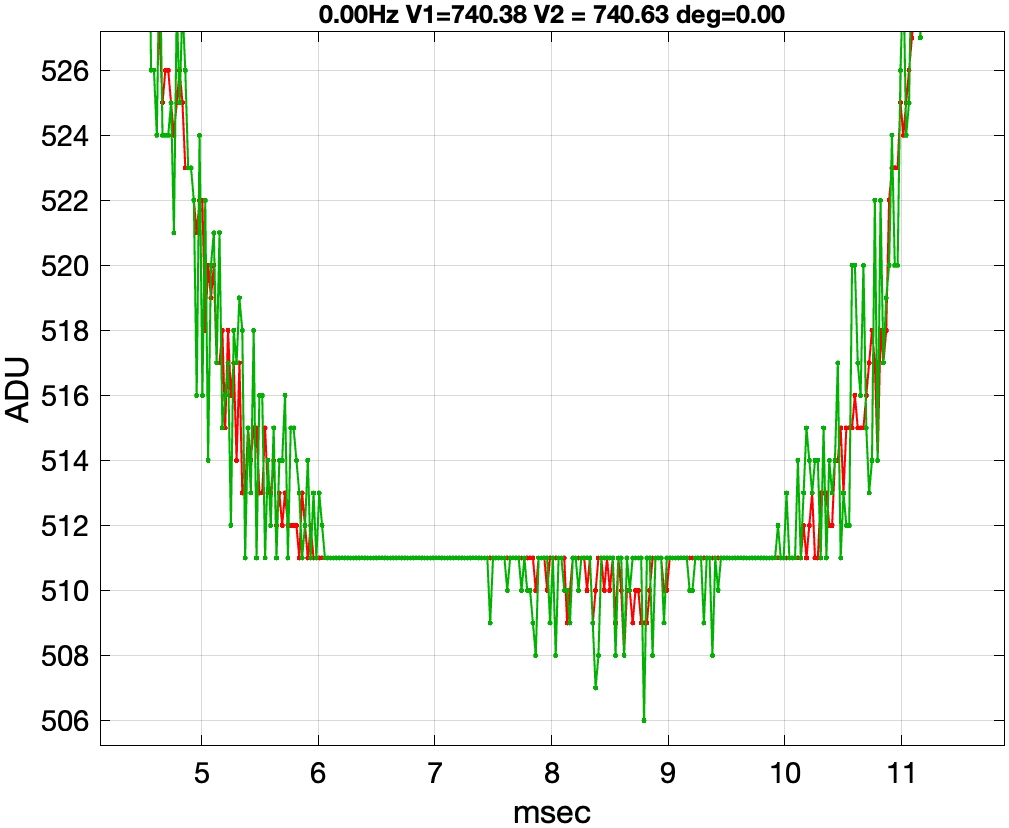

    Figure 5. Bottom of a 7.86 Hz triangle wave -- how much of this nonlinearity is due to the $10 triangle source vs. the $4 Pico? 

Googling led me to an old discussion on this: [https://forums.raspberrypi.com/viewtopic.php?t=299904,](https://forums.raspberrypi.com/viewtopic.php?t=299904,) demonstrated in early 2021, e.g., "i find it extremely unlikely that 3 different methods all wind up perfectly hanging at 511, definitely looks like the adc is being funky" ... A Principal Software Engineer replied the [data sheet](https://datasheets.raspberrypi.com/rp2040/rp2040-datasheet.pdf) has been updated on p. 630, abbreviations: differential nonlinearity (DNL), effective number of bits (ENOB):					

`The RP2040 ADC has a DNL that is mostly flat, and below 1 LSB. However at four values — 512, 1536, 2560, and 3584 — the ADC’s DNL error peaks above this value. The ENOB for the ADC has been reduced from 9-bits (simulated) to 8.7-bits (measured), see Section 4.9.3. The DNL errors will somewhat limit the performance of the ADC dependent on use case. `						

So we're warned in the bowels of the datasheet that the 10 bit Arduino might outperform the 8.7 bit Pico for accuracy. Even though software lets the Pico specify 12 bit resolution, trust it with 3-4 bits of salt (to mix metaphors). The extra resolution can be used in places, but these nonlinear errors can also pose havoc with Fourier transforms and other analyses that are ill-conditioned to nonlinearities ([https://en.wikipedia.org/wiki/Condition_number](https://en.wikipedia.org/wiki/Condition_number)). 

My first trial with a Pico some years ago revealed high temporal jitter in the ADC system, which also wreaks havoc with FFTs. That did get fixed between then and now, we'll have to keep waiting on the ADC or switch to another uC like a Teensy ([https://www.pjrc.com/store/index.html](https://www.pjrc.com/store/index.html)). 				

### Conclusion #2

Drawing the schematic for this report (Fig. 1) made me realize the circuit was actually flawed for its intended purpose. My intention was to measure Johnson noise ([https://en.wikipedia.org/wiki/Johnson–Nyquist_noise](https://en.wikipedia.org/wiki/Johnson%E2%80%93Nyquist_noise)) across a variable high resistance, using a diode biased right around it's knee a the variable megaohm resistor. Since resistance is the 1/slope or tangent of the i-v curve, varying the diode's forward voltage approaching it's knee should be equivalent to a multi-megohm variable resistor. I think that part of the theory is sound, but Fig. 1 isn't. 

        Figure 1. Schematic.

The impedance of A0 to ground is ~ 1.8k$\Omega$ through R2 (in parallel with R3 + LM317) so I was hoping to measure a low noise level ideally >> 1ADU ~ 3.3V/2^12 ~ 81uV. To compute Johnson noise, what is the bandwidth? The minimum frequency is 1 period in 24.4msec or 41Hz. But the maximum frequency is *not *the Nyquist frequency -- that's just where aliasing begins. Aliased frequencies "fold" into the passband at full amplitude, so parasitic capacitance or other elements of the ADC system will determine $f_{maximum}$ and bandwidth. Simple answer is we don't know the BW. 

A1 measures the voltage on silicon rectifier diode D1, but it's impedance to ground is $\approx 50k\Omega || Z_{D1}$, the former from R1 + R2. So the high impedance of D1 never has an effect on the noise! There should be more Johnson noise on A1 because of R1, not because of D1, until D1 is far right of its knee and it's impedance drops near 50k. What are some numbers? 

Below the knee (and avoiding A1 ~ 511ADU), 

mvrms and last pair are ratios that would be the same IF this signal was pure Johnson noise. A1's noise is 9% more instead of 5x more is consistent with most of the noise being other common source(s) -- e.g., power supply noise on the input, ADC noise, etc. Also A0 and A1's noise aren't independent, since VR2 is part of both, although the interleaved sampling makes that dependency even more complicated. So a problematic circuit, not capable of demonstrating Johnson noise, but more than adequate to demonstrate the Pico's DNL error and low ENOB. That's worth writing about ... 